Importazione dei dati dentro MATLAB

X = readtable('SondUSAcont.xlsx', 'Sheet','SondaggioUSA','range','A1:Q1501','ReadRowNames',true);


Creazione tabella di contingenza tra le variabili partito e penacap

% Creo la tabella di contingenza tra le variabili partito e penacap
[N,chi2,p,labels] =crosstab(X.partito,X.penacap);
[I,J]=size(N);
% Il primo argomento di output di crosstab contiene la tabella di
% contingenza in formato double (senza nomi ma solo con le frequenze)
% Il secondo argomento di ouptut di crosstab contiene il valore del test
% Chi quadrato di indipendenza tra le due variabili
% Il terzo argomento di ouptut di crosstab contiene il p-value del test
% Chi quadrato di indipendenza tra le due variabili
% Il quarto argomento di ouptut di crosstab contiene una matrice con le etichette delle righe della
% tabella di contingenza (prima colonna) e le etichette delle colonne delle tabella di contingenza (seconda colonna) 


% Visualizzo la tabella di contingenza in formato table

% Costruzione della matrice di contingenza in formato table
Ntable=array2table(N,'RowNames',labels(1:I,1),'VariableNames',labels(1:J,2));

disp('Tabella di contingenza originale')

Tabella di contingenza originale


disp(Ntable)

                                  CONTRARIO    FAVOREVOLE    Non so    Non risponde
                                  _________    __________    ______    ____________

    REPUBBLICANO                     41           222          17           0      
    DEMOCRATICO ATTIVISTA            75           126          10           2      
    INDIPENDENTE                     36           125          26           0      
    DEMOCRATICO                      76           203          17           2      
    REPUBBLICANO ATTIVISTA           19           141           8           0      
    DEMOCRATICO SIMPATIZZANTE        40           129          10           1      
    REPUBBLICANO SIMPATIZZANTE       24           110          14       

Riordino della tabella

% Ntablecore contiene le risposte che ci interessano
Ntablecore=Ntable;
% Elimino le righe che contengono le risposte 'ALTRO' 'Non risponde'
% e le colonne che presentano le modalità 'Non so' 'Non risponde'
% Questo codice funziona sempre indipendentemente dalla posizione di
% "ALTRO" e "Non risponde" nella tabella di contingenza.
Ntablecore({'ALTRO' 'Non risponde'},:)=[];
Ntablecore(:,{'Non so' 'Non risponde'})=[];

%% Riordino le righe della table in modo tale da avere l'ordine che segue
%  DEMOCRATICO ATTIVISTA,   DEMOCRATICO    DEMOCRATICO SIMPATIZZANTE,  INDIPENDENTE   REPUBBLICANO SIMPATIZZANTE,   REPUBBLICANO,  REPUBBLICANO ATTIVISTA
% Si noti che questo codice funzionerà sempre indipendente dalla posizione
% delle modalità nella table di partenza
ordinerichiesto=["DEMOCRATICO ATTIVISTA",   "DEMOCRATICO" "DEMOCRATICO SIMPATIZZANTE"  "INDIPENDENTE"  "REPUBBLICANO SIMPATIZZANTE",   "REPUBBLICANO",  "REPUBBLICANO ATTIVISTA"];
NtablecoreORD= Ntablecore(ordinerichiesto,:)

NtablecoreORD = 7×2 table
                                  CONTRARIO    FAVOREVOLE
                                  _________    __________

    DEMOCRATICO ATTIVISTA            75           126    
    DEMOCRATICO                      76           203    
    DEMOCRATICO SIMPATIZZANTE        40           129    
    INDIPENDENTE                     36           125    
    REPUBBLICANO SIMPATIZZANTE       24           110    
    REPUBBLICANO                     41           222    
    REPUBBLICANO ATTIVISTA           19           141    


% Un modo alternativo da pivelli era quello di riordinare tenendo presente
% che DEMOCRATICO ATTIVISTA si trova nella riga 2, "DEMOCRATICO" nella riga
% 4, "DEMOCRATICO SIMPATIZZANTE" nella riga 6...
% NtablecoreORD=Ntablecore([2 4 6 3 7 1 5],:);

disp('Tabella in formato table con le righe riordinate')

Tabella in formato table con le righe riordinate


disp(NtablecoreORD)

                                  CONTRARIO    FAVOREVOLE
                                  _________    __________

    DEMOCRATICO ATTIVISTA            75           126    
    DEMOCRATICO                      76           203    
    DEMOCRATICO SIMPATIZZANTE        40           129    
    INDIPENDENTE                     36           125    
    REPUBBLICANO SIMPATIZZANTE       24           110    
    REPUBBLICANO                     41           222    
    REPUBBLICANO ATTIVISTA           19           141    



Creazione di una nuova tabella che visualizza le percentuali di riga

% Calcolo delle percentuali di riga rispetto al toltale di riga
% Ncoreperc è un array 7 x 2 (non è una table)
Ncoreperc=100*NtablecoreORD{:,:}./sum(NtablecoreORD{:,:},2);

% Trasformo Ncoreperc in una table
% Ntablecoreperc = tabella di contingenza in formato table contenente le
% percentuali di riga
Ntablecoreperc=array2table(Ncoreperc,'RowNames',NtablecoreORD.Properties.RowNames,'VariableNames',labels(1:2,2));

disp('Tabella di contingenza contenente le percentuali di riga')

Tabella di contingenza contenente le percentuali di riga


disp(Ntablecoreperc)

                                  CONTRARIO    FAVOREVOLE
                                  _________    __________

    DEMOCRATICO ATTIVISTA          37.313        62.687  
    DEMOCRATICO                     27.24         72.76  
    DEMOCRATICO SIMPATIZZANTE      23.669        76.331  
    INDIPENDENTE                    22.36         77.64  
    REPUBBLICANO SIMPATIZZANTE      17.91         82.09  
    REPUBBLICANO                   15.589        84.411  
    REPUBBLICANO ATTIVISTA         11.875        88.125  



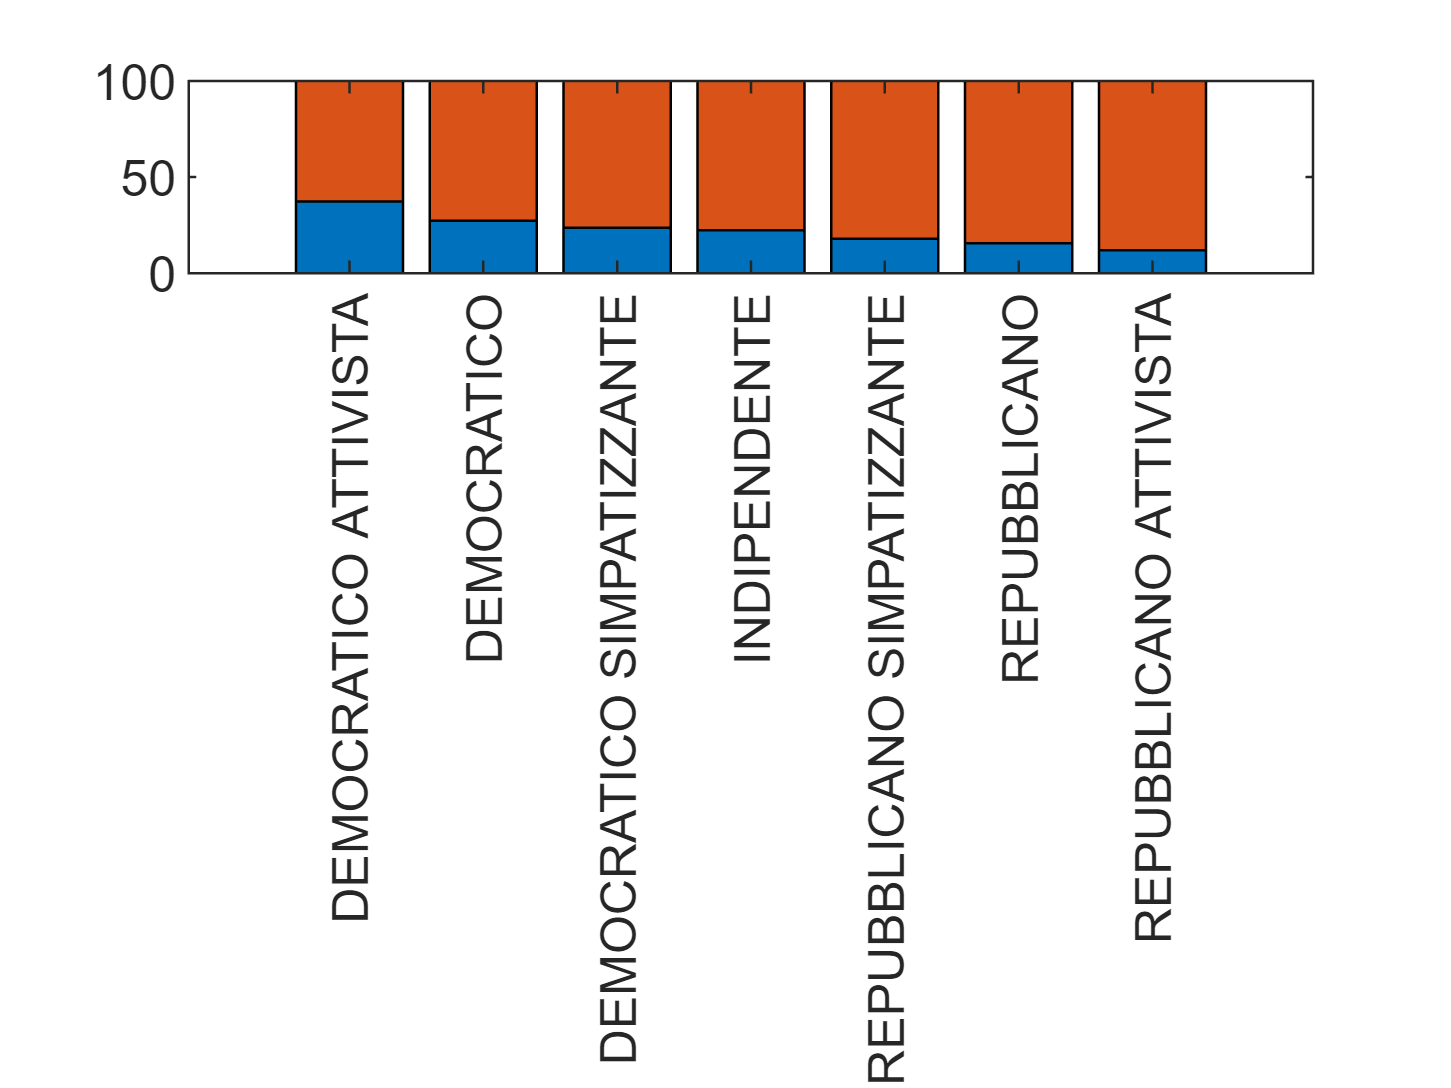


% Creo il grafico a barre sovrapposte tramite l'opzione stacked di bar
bar(Ntablecoreperc{:,:},'stacked')
set(gca,'xticklabel',Ntablecoreperc.Properties.RowNames,'XTickLabelRotation',90)

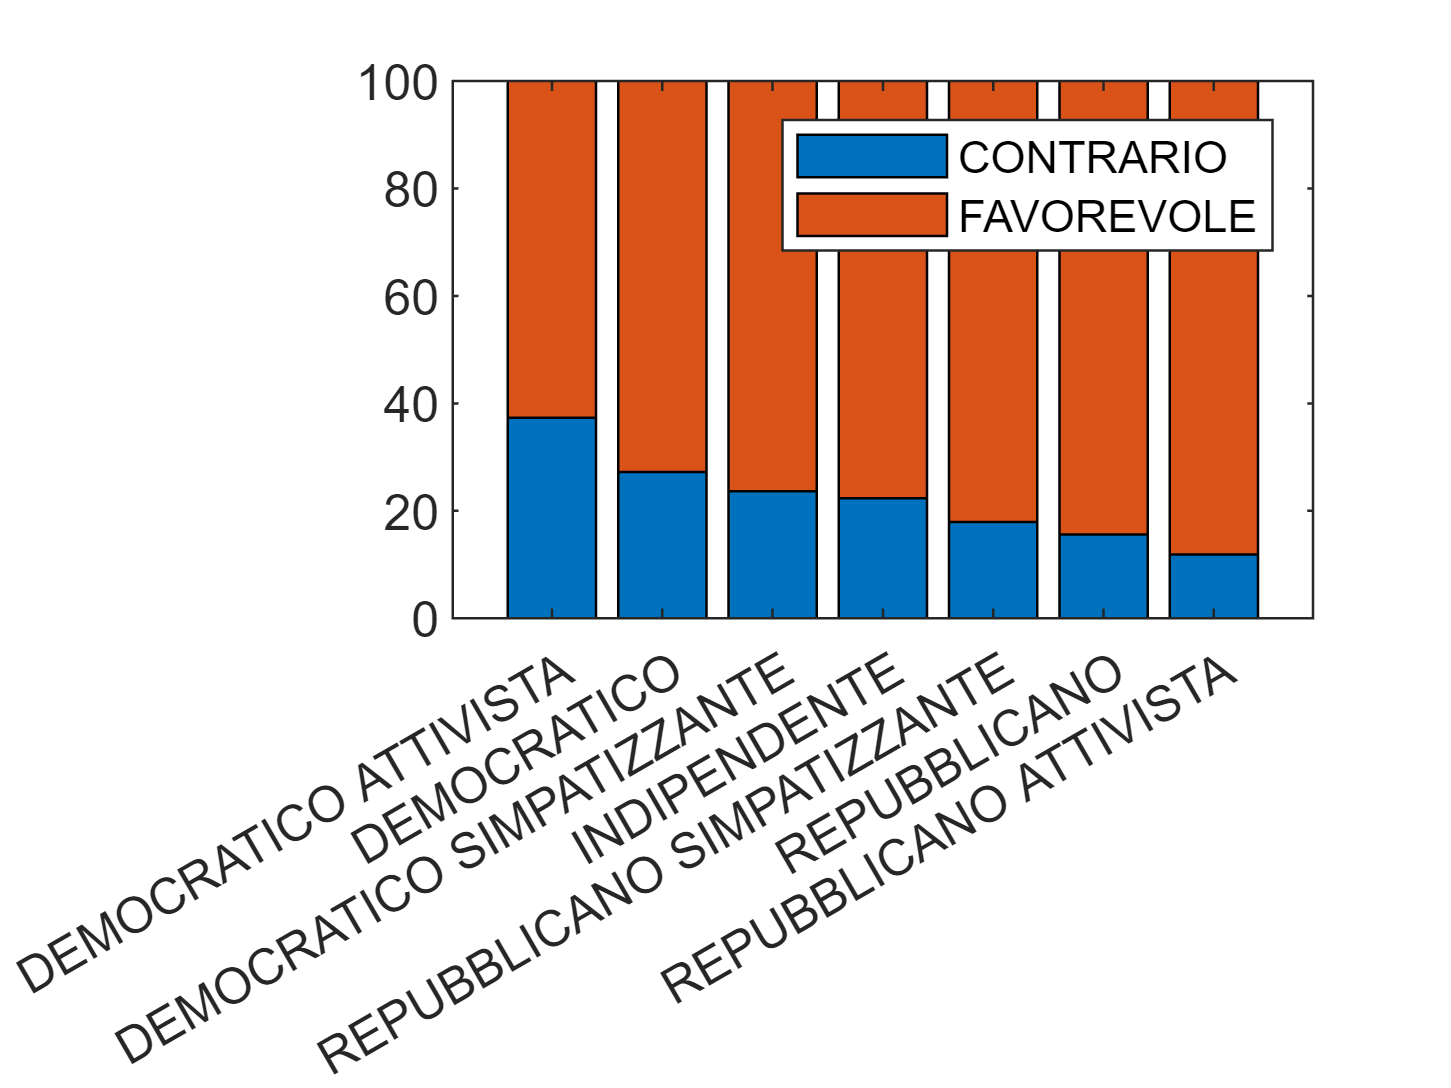

% Modo alternativo senza passare attraverso gca
nomi=Ntablecoreperc.Properties.RowNames;
bar(categorical(nomi,nomi),Ntablecoreperc{:,:},'stacked')
% Aggiunta della legenda
legend(Ntablecoreperc.Properties.VariableNames)

% Commentare il grafico che si ottiene.
% Passando da Democratico attivista a Repubblicano attivista la percentuale
% di favorevoli alla pena capitale aumenta. In altri termini andando da
% sinistra verso destra la percentuale dei favorevoli aumenta.


Calcolare l'indice Chi^2 e l’indice di Cramer per misurare l’associazione tra le due variabili

Calcolare il p-value dell'indice Chi^2. Come si distribuisce la statistica Chi^2 nel caso in esame? Che valori ci attendiamo per Chi^2 in questo caso se è vera l'ipotesi di indipendenza. Commentare i risultati ottenuti

% Calcolo manuale del test chi2
N=NtablecoreORD{:,:};
[I,J]=size(N);
n=sum(N(:));
Ntheo=sum(N,2)*sum(N,1)/n;
chi2manual=sum(((N-Ntheo).^2)./Ntheo,'all');

% Il test chi2 si distribuisce come una v.c. con (I-1)*(J-1) gradi di
% libertà. In questo caso 6 gradi di libertà. Se è vera l'ipotesi nulla mi
% attendo un valore vicino a 6.

% Calcolo manuale del p-value
% Vado a trovare la probabilità in una v.c. Chi2 con (I-1)*(J-1) 
% gradi di libertà di ottenere un valore superiore a quello osservato.
pvalmanual=chi2cdf(chi2manual,(I-1)*(J-1),'upper');


p-value molto basso, rifiuto decisamente l'ipotesi nulla di indipendenza tra "Appartenenza al partito politico" e "Posizione sulla pena di morte".

Indice di Cramer

% Indice Phi
Phi=sqrt(chi2manual/n);

% Calcolo indice di Cramer
V=Phi/sqrt(min([I-1 J-1]));
disp(['Indice di Cramer: ' num2str(V)])

Indice di Cramer: 0.18695


% L'associazione tra appartenenza al partito politico e posizione sulla
% pena capitale è pari al 19 per cento circa del valore massimo possibile.
% La posizione sulla pena di morte dipende solo per il 19%
% dall'appartenenza al partito politico e per l'81% circa dipende da altri
% fattori.

% Nei punti precedenti abbiamo visto come eliminare le modalità "Altro"
% e "non risponde" per il partito politico e le modalità "Non_so"
% "Non_risponde" per la posizione sulla pena di morte. Un modo alternativo
% di procedere è quello di definire come variabile categoriche queste due
% variabili. Questo evita i punti 4 e 5 visti in precedenza.
% Quesito. Rendere categoriche le due variabili e costruire la relativa
% tabella di contingenza.

X.partitoCAT=categorical(X.partito,ordinerichiesto);

ordinePENACAP={'CONTRARIO' 'FAVOREVOLE'};
X.penacapCAT=categorical(X.penacap,ordinePENACAP);

[Ncat,chi2cat,pcat,labels] =crosstab(X.partitoCAT,X.penacapCAT);

% Controllo che il valore del test Chi2 ed il relativo p-value siano uguali
% a quelli ottenuti tramite l'implementazione manuale precedente.

% Controllo l'uguaglianza delle implementazioni
assert(abs(chi2manual-chi2cat)<1e-10,"L'implementazione di chi2 è diversa")
assert(abs(pvalmanual-pcat)<1e-10,"L'implementazione del pvalue di chi2 è diversa")

% Costruzione della matrice di contingenza in formato table
NtableCAT=array2table(Ncat,'RowNames',labels(1:I,1),'VariableNames',labels(1:J,2));

disp('Tabella di contingenza con solo le modalità rilevanti')

Tabella di contingenza con solo le modalità rilevanti


disp(NtableCAT)

                                  CONTRARIO    FAVOREVOLE
                                  _________    __________

    DEMOCRATICO ATTIVISTA            75           126    
    DEMOCRATICO                      76           203    
    DEMOCRATICO SIMPATIZZANTE        40           129    
    INDIPENDENTE                     36           125    
    REPUBBLICANO SIMPATIZZANTE       24           110    
    REPUBBLICANO                     41           222    
    REPUBBLICANO ATTIVISTA           19           141    



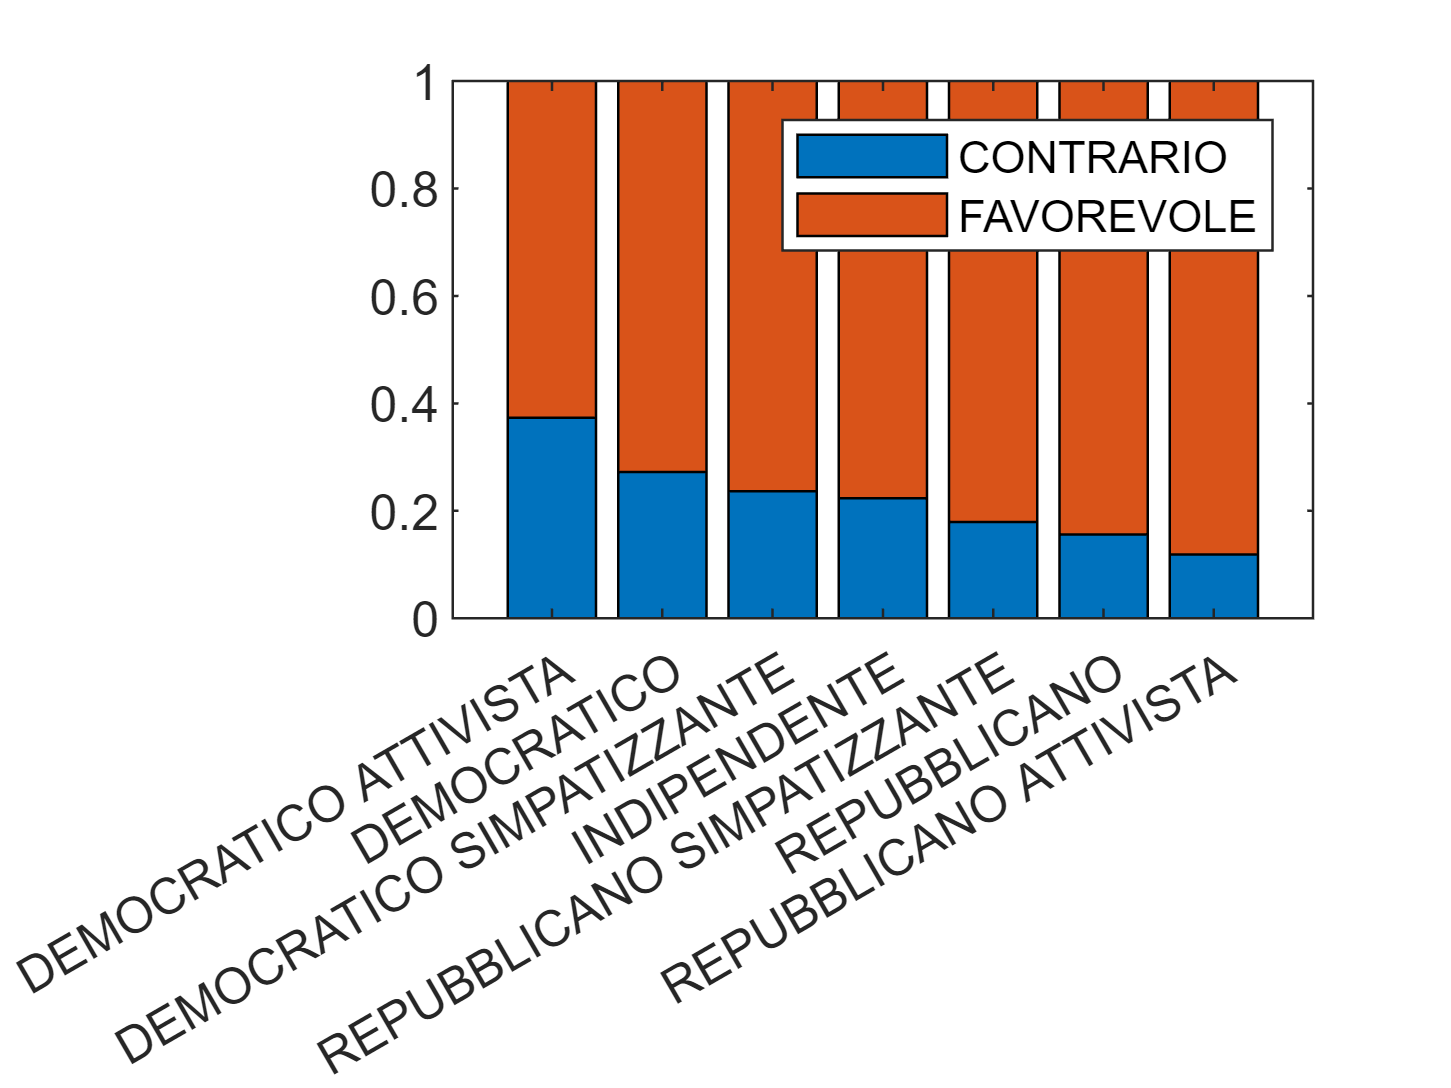


nomi1=categorical(ordinePARTITO,ordinePARTITO);
bar(nomi1,NtableCAT{:,1:2}./sum(NtableCAT{:,1:2},2),'stacked')
legend(NtableCAT.Properties.VariableNames)

Chiamata a corrNominal per calcolare in automatico tutti gli indici ed i relativi intervalli di confidenza

corrNominal(NtableCAT)

Chi2 index
   47.7785

pvalue Chi2 index
   1.3084e-08

Phi index
    0.1870

Cramer's V 
    0.1870

Test of H_0: independence between rows and columns
                   Coeff         se        zscore       pval   
                  ________    _________    ______    __________

    CramerV        0.18695     0.033203    5.6307     1.795e-08
    GKlambdayx           0            0       NaN           NaN
    tauyx         0.034951     0.010156    3.4413    0.00057897
    Hyx           0.032349    0.0092482    3.4978    0.00046907

-----------------------------------------
Indexes and 95% confidence limits
                   Value      StandardError    ConflimL    ConflimU
                  ________  

ans = struct with fields:
               N: [7×2 double]
          Ntable: [7×2 table]
            Chi2: 47.7785
        Chi2pval: 1.3084e-08
             Phi: 0.1870
         CramerV: [0.1870 0.0332 5.6307 1.7950e-08]
      GKlambdayx: [0 0 NaN NaN]
           tauyx: [0.0350 0.0102 3.4413 5.7897e-04]
             Hyx: [0.0323 0.0092 3.4978 4.6907e-04]
         ConfLim: [4×4 double]
    ConfLimtable: [4×4 table]
         TestInd: [4×4 double]
    TestIndtable: [4×4 table]


Tutti gli intervalli di confidenza no contengono il valore 0. La relazione è significativa.